% Read in original RGB image.
rgbImage = imread('a.jpeg');


% Extract color channels.
redChannel = rgbImage(:,:,1); % Red channel
img1=im2gray(redChannel);
T1 = graythresh(img1)

T1 = 0.5059

greenChannel = rgbImage(:,:,2); % Green channel
% calculate Threshold
img2=im2gray(greenChannel);
T2 = graythresh(img2)

T2 = 0.4667

blueChannel = rgbImage(:,:,3); % Blue channel
img3=im2gray(blueChannel);
T3 = graythresh(img3)

T3 = 0.4667

THC=mean(T1+T2+T3)

THC = 1.4392

fR=redChannel-THC;
fG=greenChannel-THC;
fB=blueChannel-THC;
rgbNew=cat(3,fR, fG, fB);
Ravg=(sum(sum(redChannel)))./((size(redChannel,1)).*(size(redChannel,2)));
    Gavg=(sum(sum(greenChannel)))./((size(greenChannel,1)).*(size(greenChannel,2)));
    Bavg=(sum(sum(blueChannel)))./((size(blueChannel,1)).*(size(blueChannel,2)));
    rgbNew_Avg=cat(3,Ravg, Gavg, Bavg)

rgbNew_Avg = rgbNew_Avg(:,:,1) =

  155.1002


rgbNew_Avg(:,:,2) =

  136.9345


rgbNew_Avg(:,:,3) =

  137.4517


  Ravg1=(sum(sum(fR)))./((size(fR,1)).*(size(fR,2)));
    Gavg1=(sum(sum(fG)))./((size(fG,1)).*(size(fG,2)));
    Bavg1=(sum(sum(fB)))./((size(fB,1)).*(size(fB,2)));
    rgbNew_Avg1=cat(3,Ravg, Gavg, Bavg)

rgbNew_Avg1 = rgbNew_Avg1(:,:,1) =

  155.1002


rgbNew_Avg1(:,:,2) =

  136.9345


rgbNew_Avg1(:,:,3) =

  137.4517


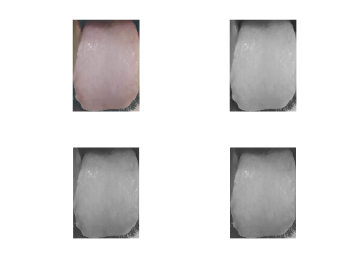

subplot(2,2,1)
imshow(rgbImage)
subplot(2,2,2)
imshow(redChannel)
subplot(2,2,3)
imshow(greenChannel)
subplot(2,2,4)
imshow(blueChannel)

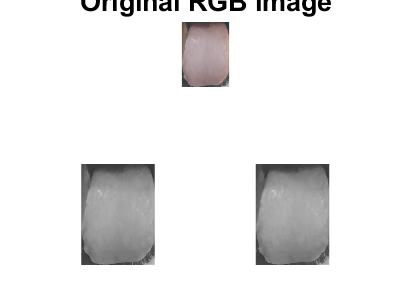

% Create an all black channel.
allBlack = zeros(size(rgbImage, 1), size(rgbImage, 2), 'uint8');
% Create color versions of the individual color channels.
just_red = cat(3, redChannel, allBlack, allBlack);
just_green = cat(3, allBlack, greenChannel, allBlack);
just_blue = cat(3, allBlack, allBlack, blueChannel);
% Recombine the individual color channels to create the original RGB image again.
recombinedRGBImage = cat(3, redChannel, greenChannel, blueChannel);
% Display them all.
subplot(3, 3, 2);
imshow(rgbImage);
fontSize = 20;
title('Original RGB Image', 'FontSize', fontSize)

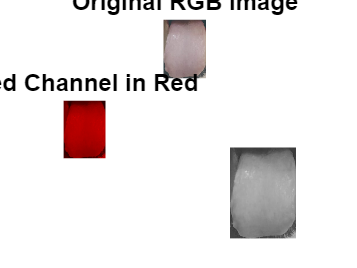

subplot(3, 3, 4);
imshow(just_red);
title('Red Channel in Red', 'FontSize', fontSize)

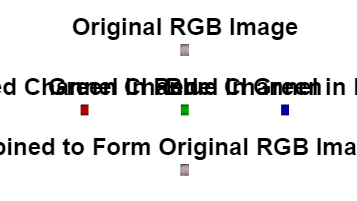

subplot(3, 3, 5);
imshow(just_green)
title('Green Channel in Green', 'FontSize', fontSize)
subplot(3, 3, 6);
imshow(just_blue);
title('Blue Channel in Blue', 'FontSize', fontSize)
subplot(3, 3, 8);
imshow(recombinedRGBImage);
title('Recombined to Form Original RGB Image Again', 'FontSize', fontSize)
% Set up figure properties:
% Enlarge figure to full screen.
set(gcf, 'Units', 'Normalized', 'OuterPosition', [0, 0, 1, 1]);
% Get rid of tool bar and pulldown menus that are along top of figure.
% set(gcf, 'Toolbar', 'none', 'Menu', 'none');
% Give a name to the title bar.
set(gcf, 'Name', 'Demo by ImageAnalyst', 'NumberTitle', 'Off')

%% binarize the image
img = imread('a.jpeg');
img=rgb2gray(img)

img = 366×266 uint8 matrix
   77   77   77   78   79   80   82   83   84   85   85   86   89   92   91   88   80   73   67   66   67   67   67   66   64   63   61   61   60   60   59   59   57   57   57   57   57   56   55   54   53   53   53   53   53   53   53   53   53   53
   77   77   77   78   79   81   83   84   85   85   86   87   90   92   92   89   82   76   69   67   67   67   66   66   64   63   61   61   60   60   59   59   57   57   57   57   57   56   55   54   53   53   53   53   53   53   53   53   53   53
   77   77   77   78   79   81   83   84   85   86   87   88   90   93   93   90   85   79   72   69   67   66   65   66   65   63   62   60   60   60   59   58   57   57   57   57   57   56   55   54   53   53   53   53   53   53   53   53   53   53
   78   78   78   79   80   82   83   84   85   87   88   89   91   94   94   92   87   81   75   71   68   65   65   66   65   64   62   60   60   59   59   58   57   57   57   57   56   56   55   54   53   53   53   53

T = graythresh(img)

T = 0.4745

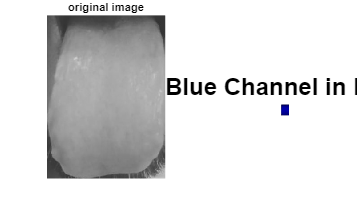

BW = imbinarize(img,T);
subplot(1,2,1)
imshow(img); title('original image');

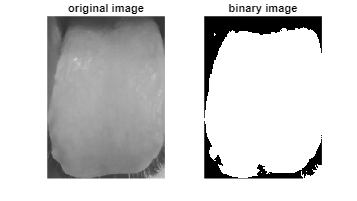

subplot(1,2,2)
imshow(BW); title('binary image');

I = imread('a.jpeg');
% Separate to RGB channel
Ir = I(:,:,1);
Ig = I(:,:,2);
Ib = I(:,:,3);
% Extract the background (black) region
Igray = rgb2gray(I);
idx = Igray == 0;
% Calculate average RGB of the region
Rave = uint8(mean(Ir(~idx)))

Rave = uint8
155

Gave = uint8(mean(Ig(~idx)))

Gave = uint8
137

Bave = uint8(mean(Ib(~idx)))

Bave = uint8
137

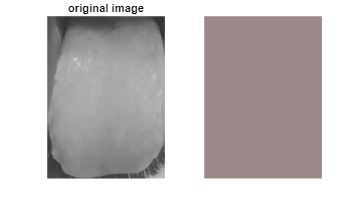

% Set the region to average RGB
Ir(~idx) = Rave;
Ig(~idx) = Gave;
Ib(~idx) = Bave;
Iout = cat(3,Ir,Ig,Ib);
% View the result
imshow(Iout)

I = imread('a.jpeg');
I=rgb2gray(I)

I = 366×266 uint8 matrix
   77   77   77   78   79   80   82   83   84   85   85   86   89   92   91   88   80   73   67   66   67   67   67   66   64   63   61   61   60   60   59   59   57   57   57   57   57   56   55   54   53   53   53   53   53   53   53   53   53   53
   77   77   77   78   79   81   83   84   85   85   86   87   90   92   92   89   82   76   69   67   67   67   66   66   64   63   61   61   60   60   59   59   57   57   57   57   57   56   55   54   53   53   53   53   53   53   53   53   53   53
   77   77   77   78   79   81   83   84   85   86   87   88   90   93   93   90   85   79   72   69   67   66   65   66   65   63   62   60   60   60   59   58   57   57   57   57   57   56   55   54   53   53   53   53   53   53   53   53   53   53
   78   78   78   79   80   82   83   84   85   87   88   89   91   94   94   92   87   81   75   71   68   65   65   66   65   64   62   60   60   59   59   58   57   57   57   57   56   56   55   54   53   53   53   53  

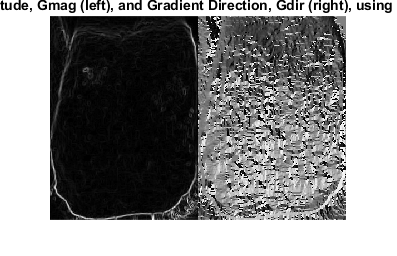

[Gmag, Gdir] = imgradient(I,'prewitt');
figure
imshowpair(Gmag, Gdir, 'montage');
title('Gradient Magnitude, Gmag (left), and Gradient Direction, Gdir (right), using Prewitt method')

I = imread('a.jpeg');
I=rgb2gray(I)

I = 366×266 uint8 matrix
   77   77   77   78   79   80   82   83   84   85   85   86   89   92   91   88   80   73   67   66   67   67   67   66   64   63   61   61   60   60   59   59   57   57   57   57   57   56   55   54   53   53   53   53   53   53   53   53   53   53
   77   77   77   78   79   81   83   84   85   85   86   87   90   92   92   89   82   76   69   67   67   67   66   66   64   63   61   61   60   60   59   59   57   57   57   57   57   56   55   54   53   53   53   53   53   53   53   53   53   53
   77   77   77   78   79   81   83   84   85   86   87   88   90   93   93   90   85   79   72   69   67   66   65   66   65   63   62   60   60   60   59   58   57   57   57   57   57   56   55   54   53   53   53   53   53   53   53   53   53   53
   78   78   78   79   80   82   83   84   85   87   88   89   91   94   94   92   87   81   75   71   68   65   65   66   65   64   62   60   60   59   59   58   57   57   57   57   56   56   55   54   53   53   53   53  

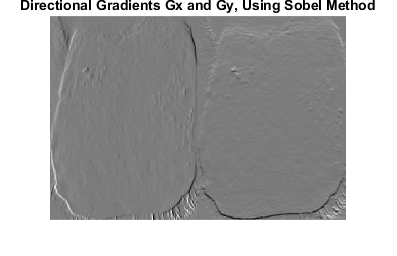

[Gx,Gy] = imgradientxy(I);
figure
imshowpair(Gx,Gy,'montage')
title('Directional Gradients Gx and Gy, Using Sobel Method')

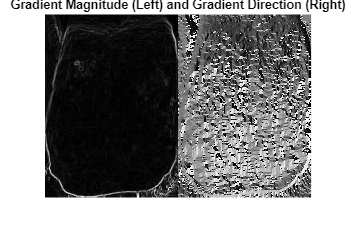


[Gmag,Gdir] = imgradient(Gx,Gy);
imshowpair(Gmag,Gdir,'montage')
title('Gradient Magnitude (Left) and Gradient Direction (Right)')

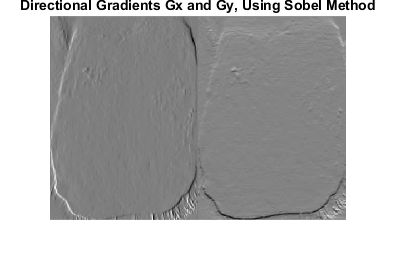

redChannel = rgbImage(:,:,1); % Red channel
img1=im2gray(redChannel);
[Gx,Gy] = imgradientxy(img1);
figure
imshowpair(Gx,Gy,'montage')
title('Directional Gradients Gx and Gy, Using Sobel Method')